# 85 - Solvej

## Finding values

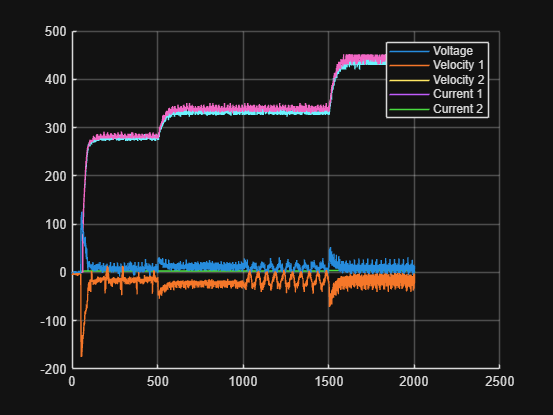

clc
clear

dd = load('device-monitor-241023-123400.log');
time_start = 0;
time_end = 50;
time_slice = dd(dd(:,1) >= time_start & dd(:,1) <= time_end, :);
i_0 = mean(time_slice(:, 5));
time_start = 150;
time_end = 450;
time_slice = dd(dd(:,1) >= time_start & dd(:,1) <= time_end, :);
i_const = mean(time_slice(:, 5));

figure(1000)
hold on
plot(dd(:,1), dd(:,2))
hold on
plot(dd(:,1), dd(:,3))
hold on
plot(dd(:,1), dd(:,4))
hold on
dd(:,5) = dd(:,5) - i_0;
plot(dd(:,1), dd(:,5))
hold on
dd(:,6) = dd(:,6) - i_0;
plot(dd(:,1), dd(:,6))
hold on
grid on
legend('Voltage', 'Velocity 1', 'Velocity 2', 'Current 1', 'Current 2')
hold off

imax = max(dd(:,6));
izero = mean(dd(1:100,6)); % 50ms
i_ss = (imax - izero)*0.0045 % mA

i_ss = 0.0776

%i_ss = (imax - izero)*0.0045;
V_ss = 3;
R = V_ss / i_ss % Ohm

R = 38.6473

time_start_3v = 650;
time_end_3v = 1500;
ss_3v = dd(dd(:,1) >= time_start_3v & dd(:,1) <= time_end_3v, :);

time_start_4v = 1630;
time_end_4v = 2000;
ss_4v = dd(dd(:,1) >= time_start_4v & dd(:,1) <= time_end_4v, :);

omega_3v = mean(ss_3v(:, 3));
omega_4v = mean(ss_4v(:, 3));
tau = (omega_4v - omega_3v) * 0.63;
L = tau*R*0.001 % H

L = 2.5179

i_ss = 0.071; % define i_ss for our robot
v_R = i_ss*L

v_R = 0.1788

v_e = 3 - v_R % back EMF

v_e = 2.8212

K_b = v_e / omega_3v % rad/s

K_b = 0.0085

K_t = K_b;
D = (i_ss * K_b) / omega_3v

D = 1.8095e-06

J = ((D*R + K_t*K_b) / R) * (tau/1000)

J = 2.3910e-07

time_start = 1500;
time_end = 1585;
time_slice = dd(dd(:,1) >= time_start & dd(:,1) <= time_end, :);
mean(time_slice(:, 5));
current_time = 27.677 * 0.63

current_time = 17.4365

s = tf('s');
G = (K_t * 10^7) / ((J*L*s^2 + D*L*s + J*R*s + D*R + K_t*K_b) * 10^7)

G =
 
         8.479e04
  -----------------------
  6.02 s^2 + 138 s + 1418
 
Continuous-time transfer function.
Model Properties


## P-controller design

Gn = [K_t];
Gd = [J*L, D*L+J*R, D*R + K_t*K_b];
G = minreal(tf(Gn, Gd))

G =
 
        1.409e04
  ---------------------
  s^2 + 22.92 s + 235.6
 
Continuous-time transfer function.
Model Properties


Ts = 0.004;
Gz = c2d(G, 0.004,'zoh')

Gz =
 
     0.1093 z + 0.106
  ----------------------
  z^2 - 1.909 z + 0.9124
 
Sample time: 0.004 seconds
Discrete-time transfer function.
Model Properties


h = figure(100);
bode(G)
hold on
bode(Gz)
legend('continuous','Ts = 4ms')
grid on
title('robot mass not included, Ts=4ms')
axis([1,1000,-200,0])
saveas(h,'bode_no_mass_ts4ms.png')
%% Matlab motor model
Vmax = 9;     % max motor voltage
gear = 9.6;
Wrad = 0.03;  % wheel radius
detect_delay = 0.03; % velocity delay
R = 4.1; L = 4.1e-3; Kb = 0.0074;
Kt = Kb; D = 0.93e-6; J = 1.01e-6;
Gn = [Kt];
Gd = [J*L, D*L+J*R, D*R + Kt*Kb];
G = minreal(tf(Gn, Gd));
Ts = 0.004;
G.OutputDelay = detect_delay;
Gz = c2d(G, Ts,'zoh')

Gz =
 
           2.02 z^2 + 4.743 z + 0.1425
  z^(-8) * ---------------------------
            z^2 - 0.9636 z + 0.01825
 
Sample time: 0.004 seconds
Discrete-time transfer function.
Model Properties


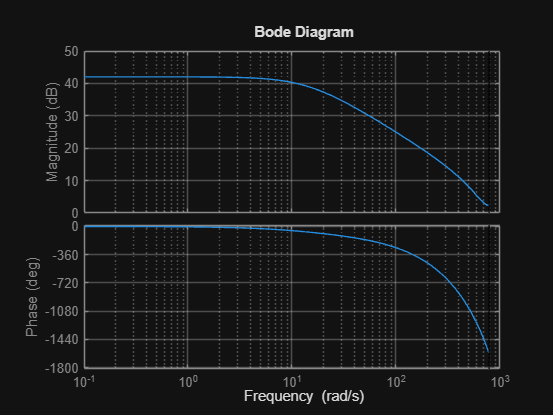

H = figure(170);
bode(Gz)
grid on

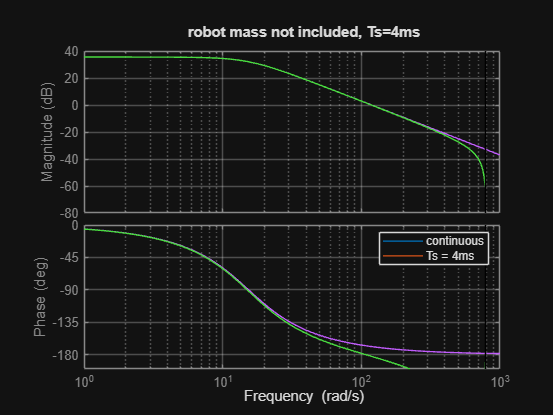

saveas(h, 'bode_with_delay_30ms.png');

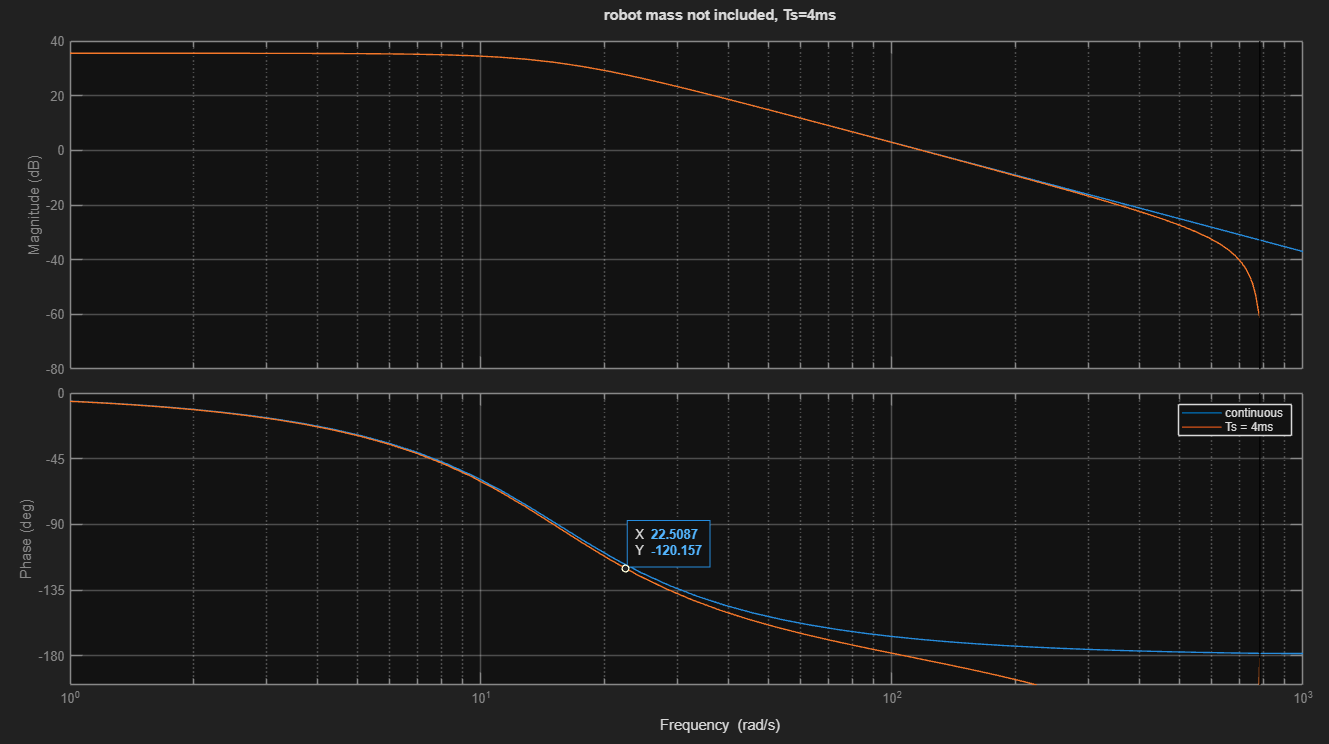

%% controller
wc = 22.5;  % crossover frequency
mag = bode(Gz,wc); % get magnitude at wc
Kp = 1/mag;          % calculate Kp
out = sim('p_controller.slx');  %'basebot_model.slx'

out =   Simulink.SimulationOutput:

                 simout: [1x1 timeseries] 
                   tout: [2936x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


h = figure(180);

h =   Figure (180) with properties:

      Number: 180
        Name: ''
       Color: [0.1294 0.1294 0.1294]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


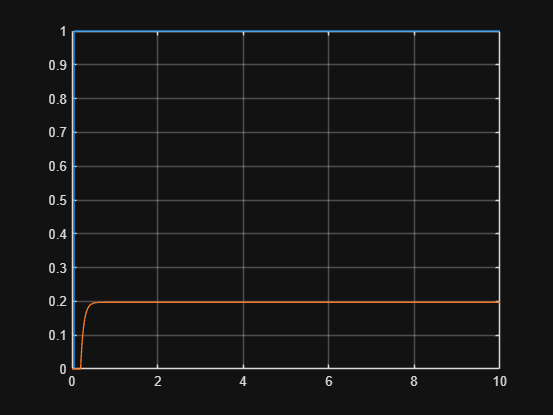

hold off
plot(out.simout.Time, out.simout.Data(:,1));
hold on
plot(out.simout.Time, out.simout.Data(:,2));
grid on
saveas(h,'step_response_kp=0.018.png')